% 已知参数
fc = 10000; % 截止频率，单位：Hz
wc = 2*pi*fc; % 截止角频率，单位：rad/s
zeta = 0.707; % 阻尼比

% 计算 L 和 C 的关系
% 由 wc = 1/sqrt(LC) 和 zeta = R/2 * sqrt(C/L) 推导
% 设 L = 1H（可任意设一个值，后续根据关系求 C 和 R）
L = (22/6)*1E-6;
C = 1/(wc^2 * L);
R = 2 * zeta * sqrt(L/C);

% 输出设计出的电阻、电容和电感值
fprintf('设计出的电感值 L = %.6f H\n', L);

设计出的电感值 L = 0.000004 H


fprintf('设计出的电容值 C = %.6e F\n', C);

设计出的电容值 C = 6.908263e-05 F


fprintf('设计出的电阻值 R = %.6f Ω\n', R);

设计出的电阻值 R = 0.325762 Ω



% 建立 LRC 滤波器的传递函数
num = 1;
den = [L*C, R*C, 1];
sys = tf(num, den);

% 生成阶跃信号的时间范围
t = linspace(0, 0.001, 1000); % 时间范围从 0 到 1ms，共 1000 个点

% 计算阶跃响应
y = step(sys, t);

% 计算输出电压波动
steady_state_value = y(end); % 稳态值取响应曲线最后一个点的值
max_output_value = max(y);
output_voltage_fluctuation = max_output_value - steady_state_value;
fprintf('输出电压波动: %.6f V\n', output_voltage_fluctuation);

输出电压波动: 0.043243 V



% 检查系统是否为欠阻尼状态（0 < zeta < 1）
if (zeta > 0) && (zeta < 1)
    % 计算超调量（百分比）
    M_p = exp(-zeta * pi / sqrt(1 - zeta^2)) * 100;
    fprintf('超调量: %.2f%%\n', M_p);
else
    fprintf('系统处于临界阻尼或过阻尼状态，无超调。\n');
end

超调量: 4.33%



% 计算电容电压纹波（使用稳定后的电压峰峰值）
% 假设从 80% 时间点后系统进入稳定状态
steady_start_index = round(length(y) * 0.8);
steady_y = y(steady_start_index:end);
capacitor_voltage_ripple = max(steady_y) - min(steady_y);
fprintf('电容电压纹波: %.6f V\n', capacitor_voltage_ripple);

电容电压纹波: 0.000000 V


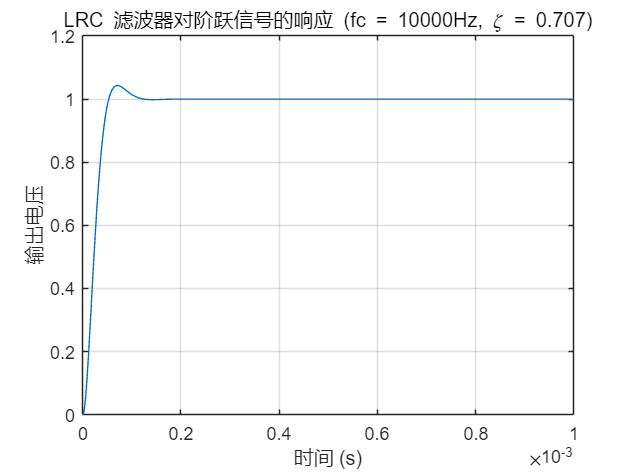


% 绘制阶跃响应曲线
figure;
plot(t, y);
grid on;
title(['LRC 滤波器对阶跃信号的响应 (fc = ', num2str(fc), 'Hz, \zeta = ', num2str(zeta), ')']);
xlabel('时间 (s)');
ylabel('输出电压');